clc; clearvars;

Set parameters

paramPath = "C:\Users\tely1\OneDrive\Desktop\EEJ9903\lidar_model\systemParam.mat";
load(paramPath);

params.lambda = 2.991e-7;
% params.
% save(paramPath,"-struct","params");

% P = simLidar(paramPath);

Load real data

addpath(genpath("C:\Users\tely1\OneDrive - The City College of New York\Matlab Onedrive\O3_Lidar\proc_functions"))
dataPath = "C:\Users\tely1\Downloads\20260423";

data_format     = "bin";
prefix = "ol";

[scaled_data,times,configs] = read_lidar_datafiles(dataPath,data_format,prefix);
scaled_data = scaled_data(1:8000,:,:,:);

times = times(:,2);

num_bins = size(scaled_data,1);
num_files = size(scaled_data,2);
num_devices = size(scaled_data,3);

dz = 3.75;
h = (dz.*(1:num_bins))';
hkm = h./1000;

id = 7;
TR = 2;

td = 270;
data_an = scaled_data(:,id,TR,1);
data_pc = scaled_data(:,id,TR,2);
data_pc = data_pc./(1-data_pc/td);

bg_an = mean(data_an(7000:end));
bg_pc = mean(data_pc(7000:end));

pc = data_pc - bg_pc;

an = data_an - bg_an;
an_cnvt = glue_an_pc(an,pc,3,60);

R_km = R./1000;

load("Ns.mat")
Ns(R_km<.07) = NaN;
Ns = Ns .* 40;

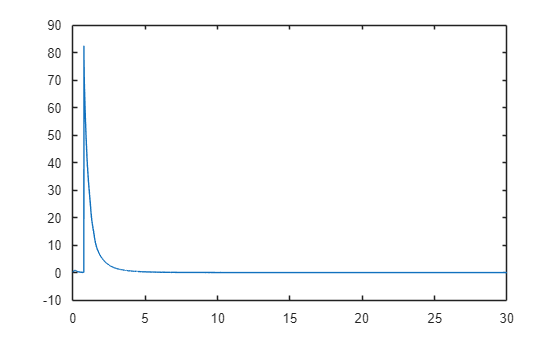

figure;
plot(hkm,an)

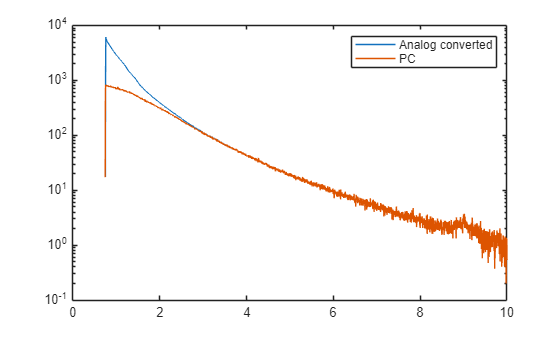

figure;
semilogy(hkm,an_cnvt,'DisplayName','Analog converted')
hold on
plot(hkm,pc,'DisplayName','PC')
hold off
legend
xlim([0 10])

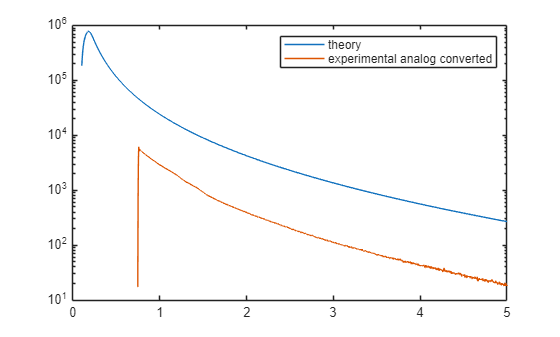

figure;
semilogy(R_km,Ns,'DisplayName','theory')
hold on
plot(hkm,an_cnvt,'DisplayName','experimental analog converted')
% plot(hkm,pc,'DisplayName','experimental pc')

hold off
legend
xlim([0 5])

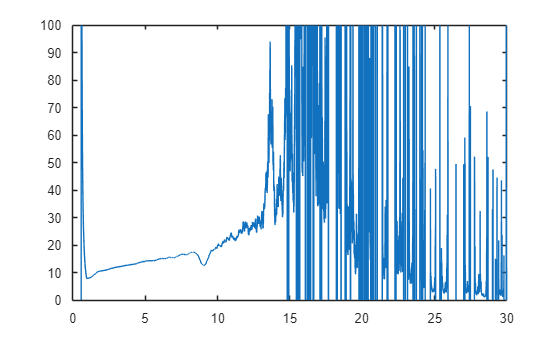

figure;
plot(hkm,Ns'./movmean(an_cnvt,100))
% plot(hkm,movmean(an_cnvt,100)./Ns')
ylim([0 100])

% ylim([0 40])

% figure;
% plot(R_km,P.*R.^2,'DisplayName','theory')
% hold on;
% plot(hkm,P_an.*h.^2,'DisplayName','experiment')
% hold off;
% xlabel('Altitude (km)')
% % ylabel('Received Photon Rate (MHz)')
% grid on;
% ax = gca;
% ax.MinorGridAlpha = 0;
% xlim([0 5])
% legend
% title('R^2 analog data')